# MAE 6760 Model Based Estimation

# Final Project

### Yihan Zhu

### Dec 17th 2021

## Model Dynamics:

### Differential drive robot

## $\[X =
\left[
\begin{array}{@{}c@{}} x \\ y  \\ \theta \end{array}
\right] 
\end{array}
\right] 
\]$,    $\[
\left[
\begin{array}{@{}c@{}} \dot{x} \\ \dot{y}  \\ \dot{\theta} \end{array}
\right] = 
\left[
\begin{array}{@{}c@{}} 
V \cos(\theta)\\ 
V \sin(\theta) \\ 
w_{\mathrm} 
\end{array}
\right] 
\]$

## 
$$\[u=
\left[
\begin{array}{@{}c@{}} V \\ \omega \end{array}
\right] 
\]$$


## 
$$\[
Z_{depth} = h(x,y,\theta) 
\]$$
    

### Z is depth measurement from the camera installed on the robot to the obstacle.

## Load simulated data

clear all; close all

% load simulation data
% truthPose[nx4], [t,x,y,theta;...]
% odometry[nx3], [t,dx,dtheta]
% rsdepth[nx11], [t,dt,msmt1,msmt2,...,msmt9]

load dataStore_freeRun.mat

% true states
trueState = dataStore.truthPose(:,2:4);
% time stamps
tstamp = dataStore.truthPose(:,1);
% odometry readings
uOdom = dataStore.odometry(:,2:3);
% depth measurements
Zdepth = dataStore.rsdepth(:,3:11);

% % plot the true trajectory
load compMap.mat
% % plot
% plot_birdseyeview(trueState(2:4,:),[],[],'True trajectory');
% drawMap(map);
% legend off


sensorOrigin = [0,0.08];
Gfun = @(x,u) GjacDiffDrive(x,u);
n_rs_rays = 9;
angles = linspace(27,-27,n_rs_rays)/180*pi;
numAng = length(angles);

% process noise and measurement noise
Q = 0.001*eye(3);    % Process noise covariance
% R(3,3) = 0.001;
R = 1*eye(numAng);  % Measurement noise covariance

% depth measurement function
hfun = @(x) depthPredict(x,map,sensorOrigin,angles);
Hfun = @(x) HjacDepth(x,map,sensorOrigin,numAng);



## offline EKF with consistency check

%Extended Kalman Filter (EKF)

X0=trueState(1,:)'; %initial state
P0=diag([0.5^2 0.5^2 0.1^2]); %initial covariance
numSteps = length(dataStore.truthPose);
n=length(X0);

xhatp=X0;Pp(1:n,1:n,1)=P0;
xhatu=X0;Pu(1:n,1:n,1)=P0;


% Consistency check
Pgate = 0.8; alpha = 1-Pgate;
nza = 2;
Lam0 = chi2inv(Pgate, nza);
Nreject = 0; Treject = [];

for k=1:(numSteps-1)
    
    u = uOdom(k+1,:)';
    
    F = Gfun(xhatu(:,k),u);    % linearized dynamic jacobian matrix
    H = Hfun(xhatu(:,k));   % linearized measurement jacobian matrix
    
    %predict state
    xhatp(:,k+1)=integrateOdom(xhatu(:,k),u(1),u(2));
    %predict covariance
    Pp(1:n,1:n,k+1) = F*Pu(1:n,1:n,k)*F'+Q;
    
    %Kalman gain
    K = Pp(1:n,1:n,k+1)*H'*inv(H*Pp(1:n,1:n,k+1)*H'+R);
    
    % innovation
    inn = Zdepth(k+1,:)' - hfun(xhatp(:,k+1));
    S = H*Pp(1:n,1:n,k+1)*H'+R; % innovation covariance
    
    % normalize innovations
    Lam = inn'*inv(S)*inn;
    
    %Update
    if Lam>Lam0
        % skip update
        xhatu(:,k+1) = xhatp(:,k+1);
        Pu(1:n, 1:n, k+1) = Pp(1:n,1:n,k+1);
        Nreject = Nreject+1;
        Treject = [Treject; tstamp(k+1)];
    else
        % update
        xhatu(:,k+1) = xhatp(:,k+1)+K*inn;
        %         Pu(1:n,1:n,k+1) = (eye(n)-K*H)*Pp(1:n,1:n,k+1)*(eye(n)-K*H)' + K*Q*K';
        
        Pu(1:n,1:n,k+1) = (eye(n)-K*H)*Pp(1:n,1:n,k+1);
        
    end
end

%
ii_plot=[1 2];
plot_estimator_error(tstamp,trueState',xhatu,Pu,ii_plot,'EKF: X/Y Estimation Error');
subplot(1,2,1);hold on
plot(Treject, -1*ones(Nreject,1),'r*','LineWidth',1);
subplot(1,2,2);hold on
plot(Treject, -1*ones(Nreject,1),'r*','LineWidth',1);
legend('estimator error','2\sigma bound','zero error','2\sigma bound','rejected MSMT');

figure;
plot_birdseyeview(trueState',xhatu,[],'EKF: true pose vs estimation');
drawMap(map);
% legend('true trajectory','estimated trajectory','3\sigma bound','wall')
legend('true trajectory','estimated trajectory','wall')

## Offline PF with resampling check

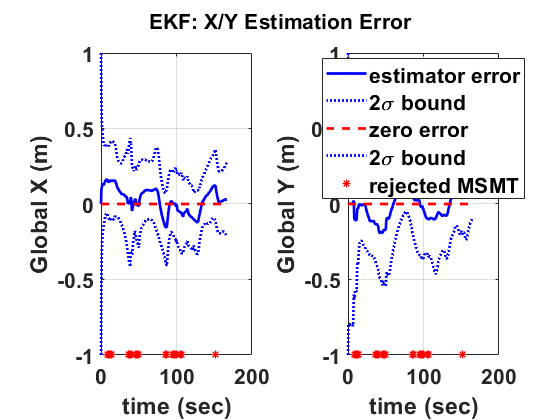

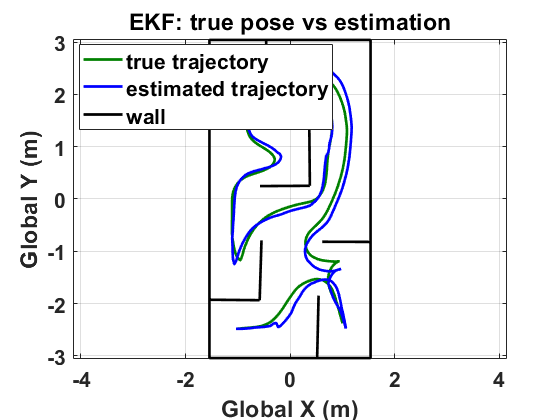

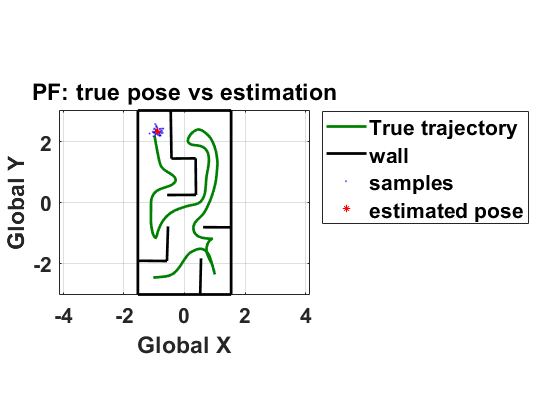


pdfnormal = makedist('Normal',0,0.5^2);

%Initialize state
ns=100;

X=zeros(ns,3,numSteps);
X(:,:,1)=[X0(1)+random(pdfnormal,ns,1) X0(2)+random(pdfnormal,ns,1) X0(3)+random(pdfnormal,ns,1)];
W=zeros(ns,numSteps);
W(:,1) = ones(ns,1)/ns;
xEst=zeros(numSteps,3);xEst(1,:)=mean(X(:,:,1),1);
xSig=zeros(numSteps,3);xSig(1,:)=std(X(:,:,1),1);

QPF = 0.001;  % process noise for PF


Neff_thresh=ns/2; %will always resample (enables SIR)

figure(10)
plot_birdseyeview(trueState',[],[],'PF: true pose vs estimation');
hold on
drawMap(map);
hPoints = plot(X(:,1,1),X(:,2,1),'b.','markersize',1);
hEst = plot(xEst(1,1),xEst(1,2),'r*','markersize',5);
legend('True trajectory','wall','samples','estimated pose','location','bestoutside')
xlabel('Global X');ylabel('Global Y');

video_name='PF_Gaussian2.mp4';
record_video=0;
if record_video
    vidfile = VideoWriter(video_name,'MPEG-4');
    vidfile.FrameRate = 10;
    open(vidfile);
    Frame(1) = getframe(10);
    writeVideo(vidfile,Frame(1));
end

for k=2:numSteps
    
    Xprior=X(:,:,k-1);
    
    %PREDICTION STEP
    w=randn(ns,3)*Q; %sample process noise
    u= uOdom(k,:); % odometry reading
    
    %     Xpred=Xprior+u+w; %predition step for all particles: k -> k+1
    %     Xpred =
    %     Xpred = integrateOdom(Xprior,u(1),u(2))+random('normal',0,sqrt(noise),[3,1]);
    
    % find xbar and weight for each particle
    for i = 1:ns
        x = Xprior(i,:);
        
        % prediction plus noise
        Xpred(i,:)= integrateOdom(x,u(1),u(2))+random('normal',0,sqrt(QPF),[3,1]);
        
        if(~insideMap(Xpred(i,:),map))
            Xpred(i,:) = Xprior(i,:);
        end
        
        % estimated measurement
        Zhat(i,:) = hfun(Xpred(i,:))';
    end
    
    %UPDATE STEP
    Zcurrent=Zdepth(k,:); %pull off current measurement
    
    Inn = ones(ns,1)*Zcurrent - Zhat; %calculate innovations for each particle
    
    %calculate likelihood weighting for each particle
    for ipart=1:ns
        L(ipart,1) = pdf(pdfnormal,Inn(ipart,1))*pdf(pdfnormal,Inn(ipart,2))*pdf(pdfnormal,Inn(ipart,3))*...
            pdf(pdfnormal,Inn(ipart,4))*pdf(pdfnormal,Inn(ipart,5))*pdf(pdfnormal,Inn(ipart,6))*...
            pdf(pdfnormal,Inn(ipart,7))*pdf(pdfnormal,Inn(ipart,8)) *pdf(pdfnormal,Inn(ipart,9)) ; %likelihoods of two indepedent msts multiply
    end
    
    %UPDATE WEIGHTS
    Wk_unnorm=W(:,k-1).*L; %update weight with unnormalized likelihood
    Wk=Wk_unnorm/sum(Wk_unnorm); %normalize all weights to sum to 1
    
    %RESAMPLING
    Neff=1/[Wk'*Wk]; %calculate effective number of particles (varies between 1 and ns)
    
    if Neff<Neff_thresh %resample if under threshold
        
        CDF = cumsum(Wk)/sum(Wk); %create a running sum function of the weights
        CDF_plus=CDF+rand(ns,1)*1E-6; %for cases when a particle weight went to zero
        %randomly (uniform) choose likely (better) particles...
        iSelect  = rand(ns,1);
        %find particle corresponding to each y value
        iNextGeneration = interp1(CDF_plus,1:ns,iSelect,'nearest','extrap');
        %copy selected particles for next generation
        X(:,:,k) = Xpred(iNextGeneration,:);
        W(:,k) = ones(ns,1)/ns;
        
    else
        X(:,:,k) = Xpred;
        W(:,k)=Wk;
    end
    
    %our estimate is the mean of the particles
    xEst(k,:) = sum(Wk.*X(:,:,k),1);
    xSig(k,:) = sqrt([sum(Wk.*(X(:,1,k)-xEst(k,1)).^2,1) ...
        sum(Wk.*(X(:,2,k)-xEst(k,2)).^2,1) ...
        sum(Wk.*(X(:,3,k)-xEst(k,3)).^2,1)]);
    
    %for bootstrap/SIR (always resample), where all weights are the same
    %xEst(k,:) = mean(X(:,:,k),1);
    %xSig(k,:) = std(X(:,:,k),1);
         
    set(hPoints,'XData',X(:,1,k));
    set(hPoints,'YData',X(:,2,k));
    set(hEst,'XData',xEst(k,1));
    set(hEst,'YData',xEst(k,2));
    drawnow;
    pause(0.05);
    
    if record_video
        Frame(k) = getframe(10);
        writeVideo(vidfile,Frame(k));
    end
    
end

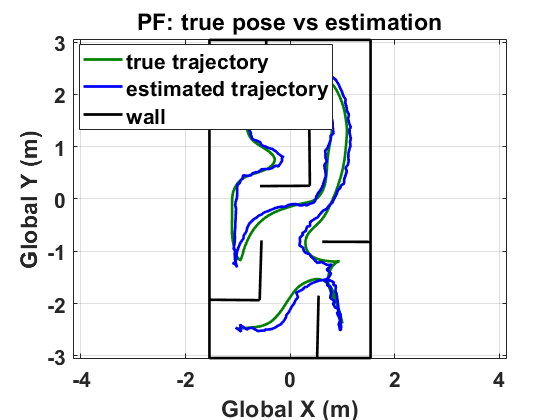

if record_video
    close(vidfile)
end

figure;
plot_birdseyeview(trueState',xEst',[],'PF: true pose vs estimation');
drawMap(map);
% legend('true trajectory','estimated trajectory','3\sigma bound','wall')
legend('true trajectory','estimated trajectory','wall')

## Plotting functions

function wall = drawMap(map,plotOpts)
% DrawMap: this function draw the walls of the map
%
%    INPUTS
%               map     Nx4 matrix, which contains the coordinates of
%                       all walls in the environment: [x1; y1; x2; y2].
%    OUTPUTS
%               plot contains the walls of the map
%   Cornell University
%   Autonomous Mobile Robots
%   Zhu, Yihan

hold on
axis equal
for i=1:length(map(:,1))
    if i==1
    wall(i)=plot([map(i,1),map(i,3)],[map(i,2),map(i,4)],'k','linewidth',2);
    else
        wall(i)=plot([map(i,1),map(i,3)],[map(i,2),map(i,4)],'k','linewidth',2,'HandleVisibility','off');
    end
end

if exist('plotOpts','var')
    % Set plot options
    Nopts = numel(plotOpts)/2;
    plotOpts = reshape(plotOpts,2,Nopts)';
    for n = 1:Nopts
        set(wall,cell2mat(plotOpts(n,1)),cell2mat(plotOpts(n,2)));
    end
end

wall = wall(1);
end


function plot_estimator_error(t,x1,x2,P2,ii_plot,title_name);
% x1 is the true value or reference comparison
% x2,P2 is the estimator state and covariance
% ii_plot: 2x1 vector of which states to plot
%
axis_names={'Global X (m)','Global Y (m)','Heading (rad)'};
figure;subplot(122);
%
for i=1:length(ii_plot),
    ii=ii_plot(i);
    subplot(1,2,i);
    err=x2(ii,:)-x1(ii,:);
    plot(t,err,'b-');
    hold on;
    if ~isempty(P2)
        plot(t,err'-2*sqrt(squeeze(P2(ii,ii,:))),'b:');
        plot(t,zeros(length(t),1),'r--');
        plot(t,err'+2*sqrt(squeeze(P2(ii,ii,:))),'b:');
    end
    hold off
    xlabel('time (sec)');ylabel(axis_names(ii));grid;
    %     xlim([0 35]);set(gca,'xtick',[0:5:35]);
end
legend('estimator error','2\sigma bound','zero error','Location','best');
%
sgtitle(title_name);
PrepFigPresentation(gcf);
end

function plot_birdseyeview(x1,x2,P2,title_name);
% x1 is the true value or reference comparison
% x2,P2 is the estimator state and covariance
%
ii_x1=[];ii_x2=[];ii_P2=[]; %for legend
% figure;
if ~isempty(x1),
    plot(x1(1,:),x1(2,:),'color',[0 0.5 0]);ii_x1=1;
end
hold on;
if ~isempty(x2),
    plot(x2(1,:),x2(2,:),'b-');ii_x2=2;
end
if ~isempty(P2),
    iell=[2 10:10:length(x2)];
    for i=1:length(iell),
        ii=iell(i);
        [Xe,Ye] = calculateEllipseCov(x2([1 2],ii),P2([1 2],[1 2],ii),3);
        plot(Xe,Ye,'m-');
    end
    ii_P2=3;
end
xlabel('Global X (m)');ylabel('Global Y (m)');grid;
hold off;
legend_names={'true trajectory','estimated trajectory','3\sigma bound'};
legend(legend_names{ii_x1},legend_names{ii_x2},legend_names{ii_P2},'Location','best')
%
title(title_name);
PrepFigPresentation(gcf);
end

function [Xe,Ye] = calculateEllipseCov(X, P, nsig, steps)
%# This functions returns points to draw an ellipse
%#
%#  @param X     x,y coordinates
%#  @param P     covariance matrix
%#

error(nargchk(2, 3, nargin));
if nargin<3, nsig = 1; end
if nargin<4, steps = 36; end

[U,S,V]=svd(P);
s1=sqrt(S(1,1));s2=sqrt(S(2,2));angle=acos(U(1,1))*180/pi;
x=X(1);
y=X(2);

%scale by nsig
s1=nsig*s1;
s2=nsig*s2;

beta = angle * (pi / 180);
sinbeta = sin(beta);
cosbeta = cos(beta);

alpha = linspace(0, 360, steps)' .* (pi / 180);
sinalpha = sin(alpha);
cosalpha = cos(alpha);

Xe = x + (s1 * cosalpha * cosbeta - s2 * sinalpha * sinbeta);
Ye = y + (s1 * cosalpha * sinbeta + s2 * sinalpha * cosbeta);

end

function PrepFigPresentation(fignum);
%
% prepares a figure for presentations
%
% Fontsize: 14
% Fontweight: bold
% LineWidth: 2
%

figure(fignum);
fig_children=get(fignum,'children'); %find all sub-plots

for i=1:length(fig_children),
    
    set(fig_children(i),'FontSize',16);
    set(fig_children(i),'FontWeight','bold');
    
    fig_children_children=get(fig_children(i),'Children');
    set(fig_children_children,'LineWidth',2);
end
end

## Other Functions

function[depth] = depthPredict(robotPose,map,sensorOrigin,angles)
% DEPTHPREDICT: predict the depth measurements for a robot given range
% measurements and angles
%
%   INPUTS
%       robotPose   	3-by-1 pose vector in global coordinates (x,y,theta)
%       map         	N-by-4 matrix containing the coordinates of walls in
%                   	the environment: [x1, y1, x2, y2]
%       sensorOrigin	origin of the sensor-fixed frame in the robot frame: [x y]
%       angles      	K-by-1 vector of the angular orientation of the range
%                   	sensor(s) in the sensor-fixed frame, where 0 points
%                   	forward. All sensors are located at the origin of
%                   	the sensor-fixed frame.
%
%   OUTPUTS
%       depth       	K-by-1 vector of depths (meters)
%
%
%   Cornell University
%   Autonomous Mobile Robots
%   Homework 2
%   Zhu, Yihan

Sx = sensorOrigin(1);
Sy = sensorOrigin(2);
k = length(angles);
range = 100*ones(k,1);
% find the walls that is in front of the robot
[num_wall,~] = size(map);

for i=1:num_wall
    % change map coordinates from global to robot
    Q1 = global2robot(robotPose,map(i,1:2));
    Q2 = global2robot(robotPose,map(i,3:4));
    x1 = Q1(1);    y1 = Q1(2);    x2 = Q2(1);    y2 = Q2(2);
    % find the distance from sensor to the wall at angle[p]
    for p=1:k
        th = angles(p);
        x3 = Sx + cos(th)*10; y3 = Sy+sin(th)*10;
        %dis=((Sy-y1)*(x2-x1)-(Sx-x1)*(y2-y1))/((y2-y1)-tan(th)*(x2-x1));
        [isect,x,y,~] = intersectPoint(Sx,Sy,x3,y3,x1,y1,x2,y2);
        if isect
            dis = sqrt((x-Sx)^2+(y-Sy)^2);
%             dis = ua*10;
        end
        % determine if there's a closer wall to the current one
        if isect && range(p)>dis %&& dis>-0.175
%             if dis<0.175
%                 dis = 0;
%             end
            range(p) = dis;
        end      
    end
end
for j=1:k
    if range(j)>=10
        range(j)=0;
    end
end


k = length(angles);
depth = zeros(k,1);
for i=1:k
    depth(i) = range(i) * cos(angles(i));    
end
end


function G = GjacDiffDrive(x, u)
% GjacDiffDrive: output the jacobian of the dynamics. Returns the G matrix
%
%   INPUTS
%       x            3-by-1 vector of pose
%       u            2-by-1 vector [d, phi]'
%
%   OUTPUTS
%       G            Jacobian matrix partial(g)/partial(x)
%
%   Cornell University
%   Autonomous Mobile Robots
%   Homework 4
%   Zhu,Yihan

G = [1	0	-u(1)*sin(x(3));
     0	1    u(1)*cos(x(3));
     0  0   1];
end




function H = HjacDepth(x, map, sensor_pos, K)
% HjacDepth: output the jacobian of the depth measurement. Returns the H matrix
%
%   INPUTS
%       x            3-by-1 vector of pose
%       map          of environment, n x [x1 y1 x2 y2] walls
%       sensor_pos   sensor position in the body frame [1x2]
%       K            number of measurements (rays) the sensor gets between 27 to -27 
%
%   OUTPUTS
%       H            Kx3 jacobian matrix
%
%   Cornell University
%   Autonomous Mobile Robots
%   Homework 4
%   Zhu,Yihan

xt = x(1);
yt = x(2);
tht = x(3);
angles = linspace(27,-27,K)/180*pi;

% find the expected depth mesurement
% rangeX = rangePredict(x,map,sensor_pos,angles);
depthX = depthPredict(x,map,sensor_pos,angles);

% setting dx, dy, dth
dx = 0.001;
dy = 0.001;
dth = 0.001;

% find h(x+dx), h(x+dy), h(x+dth)
% rangeDx = rangePredict([xt+dx;yt;tht],map,sensor_pos,angles);
% rangeDy = rangePredict([xt;yt+dy;tht],map,sensor_pos,angles);
% rangeDth = rangePredict([xt;yt;tht+dth],map,sensor_pos,angles);
depthDx = depthPredict([xt+dx;yt;tht],map,sensor_pos,angles);
depthDy = depthPredict([xt;yt+dy;tht],map,sensor_pos,angles);
depthDth = depthPredict([xt;yt;tht+dth],map,sensor_pos,angles);

% calculate H
H(:,1) = (depthDx - depthX)/dx;
H(:,2) = (depthDy - depthX)/dy;
H(:,3) = (depthDth - depthX)/dth;
end



function[xyR] = global2robot(pose,xyG)
% GLOBAL2ROBOT: transform a 2D point in global coordinates into robot
% coordinates (assumes planar world).
% 
%   XYR = GLOBAL2ROBOT(POSE,XYG) returns the 2D point in robot coordinates
%   corresponding to a 2D point in global coordinates.
% 
%   INPUTS
%       pose    robot's current pose [x y theta(radians)]  (1-by-3)
%       xyG     2D point in global coordinates (1-by-2)
% 
%   OUTPUTS
%       xyR     2D point in robot coordinates (1-by-2)
% 
% 
%   Cornell University
%   Autonomous Mobile Robots
%   Homework #1
%   Zhu, Yihan

p_x = pose(1);
p_y = pose(2);
theta = pose(3);
% rotation matrix from global to robot
R_RG = [cos(theta) sin(theta);
        -sin(theta) cos(theta)];
O_xy = R_RG * [-p_x;-p_y];
    
% transform matrix from global to robot
T_RG = [cos(theta) sin(theta) O_xy(1);
        -sin(theta) cos(theta) O_xy(2);
        0   0   1];
    
G_location = [xyG(1);xyG(2);1]; % 3 by 1, [x_G;y_G;1]
R_location = T_RG * G_location; % 3 by 1
xyR = [R_location(1), R_location(2)];
end


function[isect,x,y,ua]= intersectPoint(x1,y1,x2,y2,x3,y3,x4,y4)
% INTERSECTPOINT: find the x/y coordinates of the intersection of two line
% segments (if intersection exists)
% 
%   [ISECT,X,Y,UA] = INTERSECTPOINT(X1,Y1,X2,Y2,X3,Y3,X4,Y4) calculates the
%   intersection point of two line segments
% 
%   INPUTS
%       x1,y1   x/y coordinates of point 1 on line segment 1
%       x2,y2   x/y coordinates of point 2 on line segment 1
%       x3,y3   x/y coordinates of point 1 on line segment 2
%       x4,y4   x/y coordinates of point 2 on line segment 2
% 
%   OUTPUTS
%       isect   bool variable (true if segments intersect, false otherwise)
%       x,y     x/y coordinates of intersection point (if isect = true)
%       ua      distance of intersection point along line 1 (0 <= ua <= 1) 
%               where: x = x1 + ua (x2 - x1) 
% 
%   Refer to http://local.wasp.uwa.edu.au/~pbourke/geometry/lineline2d for
%   line segment intersection equations.
% 
%   Cornell University
%   MAE 4180/5180 CS 3758: Autonomous Mobile Robots

x = [];
y = [];
ua = [];

denom = (y4-y3)*(x2-x1)-(x4-x3)*(y2-y1);

if denom == 0
    % if denom = 0, lines are parallel
    isect = false;
    return;
else
    ua = ((x4-x3)*(y1-y3) - (y4-y3)*(x1-x3))/denom;
    ub = ((x2-x1)*(y1-y3) - (y2-y1)*(x1-x3))/denom;
    
    % if (0 <= ua <= 1) and (0 <= ub <= 1), intersection point lies on line
    % segments
    if ua >= 0 && ub >= 0 && ua <= 1 && ub <= 1
        isect = true;
        x = x1 + ua*(x2-x1);
        y = y1 + ua*(y2-y1);
    else
        % else, the intersection point lies where the infinite lines
        % intersect, but is not on the line segments
        isect = false;
        return;
    end
end
end


function [finalPose] = integrateOdom(initPose,d,phi)
% integrateOdom: Calculate the robot pose in the initial frame based on the
% odometry
% 
% [finalPose] = integrateOdom(initPose,dis,phi) returns a 3-by-N matrix of the
% robot pose in the initial frame, consisting of x, y, and theta.

%   INPUTS
%       initPose    robot's initial pose [x y theta]  (3-by-1)
%       d     distance vectors returned by DistanceSensorRoomba (1-by-N)
%       phi     angle vectors returned by AngleSensorRoomba (1-by-N)

% 
%   OUTPUTS
%       finalPose     The final pose of the robot in the initial frame
%       (3-by-N)

%   Cornell University
%   MAE 4180/5180 CS 3758: Autonomous Mobile Robots
%   Homework #2
%   Zhu, Yihan

%  number of data points
N = length(d);
finalPose = zeros(3,N);
for i = 1:N
    % read initial pose
    Ax = initPose(1);
    Ay = initPose(2);
    thA = initPose(3);
    
    d_now = d(i);
    phi_now = phi(i);
    % calculate dx dy using equations from 1.1  
    dx = cos(thA)*d_now*cos(phi_now/2)-sin(thA)*d_now*sin(phi_now/2);
    dy = sin(thA)*d_now*cos(phi_now/2)+cos(thA)*d_now*sin(phi_now/2);
    
    % find final pose
    Bx = dx+Ax;
    By = dy+Ay;
    thB = thA+phi_now;
      
    % update position
    finalPose(:,i)=[Bx;By;thB];
    initPose=finalPose(:,i);
    
%    drawRobot(initPose,0.01);
end
end



function boolean = insideMap(pose,map)
% INSIDEMAP:  determine if the robot is inside the map
%
%   INPUT:
%       pose      3x1 robot's position
%       map     Nx4 map data
%
%   OUTPUT:
%       boolean true if robot is inside the map

boolean = false;

% find the map range
xmax = max(max(map(:,1)),max(map(:,3)));
xmin = min(min(map(:,1)),min(map(:,3)));
ymax = max(max(map(:,2)),max(map(:,4)));
ymin = min(min(map(:,2)),min(map(:,4)));

x = pose(1);
y = pose(2);

if (x>xmin&&x<xmax&&y<ymax&&y>ymin)
    boolean = true;
end
end